# Assessing the Occurrence of Tularemia in Cottontail Rabbits

## Introduction

This program has the following objectives:

- Load an external data file into an array.

- Compute descriptive statistics of the data. This will include several measures of central tendency, variability, asymmetry, and the importance of outliers.

- Produce several visualizations of the data including histograms and box and whisker plots. 

## Initialization Code

Clear all memory, close all figures, and clean out the command line history

clear all; close all; clc;

Read a data set containing counts of rabbits diagnosed with tularemia out of 40 different samples of size 30.

data=csvread('DataExample.csv')

data =     10
     5
     7
     8
     6
     9
    11
    12
    11
    11


## Descriptive Statistics

Compute some of the more useful descriptive statistics.

The mean, median and mode are the three most commonly used measures of central tendency.

Mean=mean(data)

Mean = 9.5250

Median=median(data)

Median = 9.5000

Mode=mode(data)

Mode = 9

The three quartiles divide the sorted data set into four equal parts. We can use the distance between the first and third quartile to form a robust measure of variability: the interquartile range.

Q=quantile(data,[0.25 0.50 0.75])

Q =     8.0000    9.5000   12.0000


InterQuartileRange=Q(3)-Q(1)

InterQuartileRange = 4

The maximum and minumum of the data set give us a measure of the extent covered by our data set. We can, in turn, use these to find the range of our data set.

Minimum=min(data)

Minimum = 5

Maximum=max(data)

Maximum = 14

Range=Maximum-Minimum

Range = 9

Variance and Standard Deviation are each measures of variability of the data around its mean

Variance=var(data,1)

PopulationVariance = 6.2994

StdDev=std(data,1)

PopulationStdDev = 2.5099

Skewness is a measure of asymmetry around the mean and Bowley's measure for skewness is a robust measure.

Skewness=skewness(data)

Skewness = -0.2145

Bowley=(Q(3)+Q(1)-2*Q(2))/InterQuartileRange

Bowley = 0.2500

Kurtosis is a measure of the variability of the extremities of the dataset about the mean.

Kurtosis=kurtosis(data)

Kurtosis = 2.0237

## Visualization

### Histogram

A histogram gives us an overall picture of how our data is distributed. 

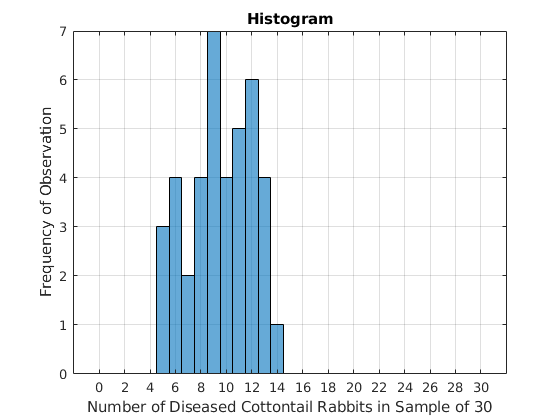

figure(1)
histogram(data,[-0.5:30.5])
title('Histogram');
xlabel('Number of Diseased Cottontail Rabbits in Sample of 30');
ylabel('Frequency of Observation');
xticks([0:2:30])
grid on

### Box and Whisker Plot

A box and whisker plot is a good way to visually summarize some of the descriptive statistics associated with our data set.  It also provides a visual measure of variability.

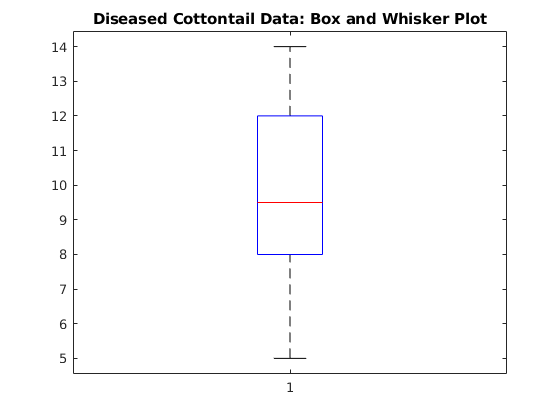

figure(2)
boxplot(data)
title('Diseased Cottontail Data: Box and Whisker Plot');

### Empirical Distribution

An empirical distribution is quite similar to a histogram, except that the bar heights represent relative frequencies of each outcome in the data set rather than absolute frequencies.

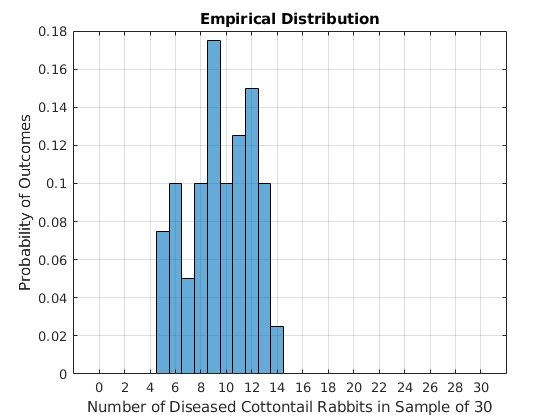

figure(3)
histogram(data,[-0.50:30.5],'Normalization','probability')
title('Empirical Distribution');
xlabel('Number of Diseased Cottontail Rabbits in Sample of 30');
ylabel('Relative Frequency of Outcomes')
xticks([0:2:30])
grid on